# Homework 3

## ADSI Problem 2.1: Implementation of All-zero lattice filters

Work you way through the MATLAB code in Figure 9.26 and make sure you understand what is going on.  

Code can be found in azlatfilt.m.

## ADSI Problem 2.2: Find impulse response of an all-zero lattice filter

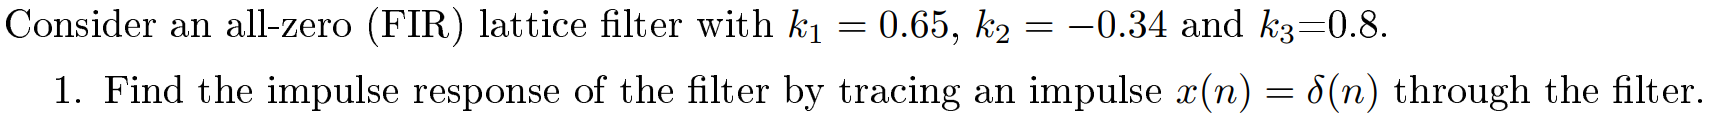

We can find the the impulse response of a filter by passing letting the impulse signal$\delta \left\lbrack n\right\rbrack$ pass through the filter:

k = [0.65, -0.34, 0.8];
x = [1, 0, 0, 0];
G = 1;
y = azlatfilt(k, x, G)

y =     1.0000    0.1570    0.0032    0.8000


The impulse response of the given filter is:


$$h\left\lbrack n\right\rbrack =\left\lbrack 1,0\ldotp 157,0\ldotp 0032,0\ldotp 8\right\rbrack$$


## ADSI Problem 2.3: Find the reflection coefficients for an all-zero lattice filter

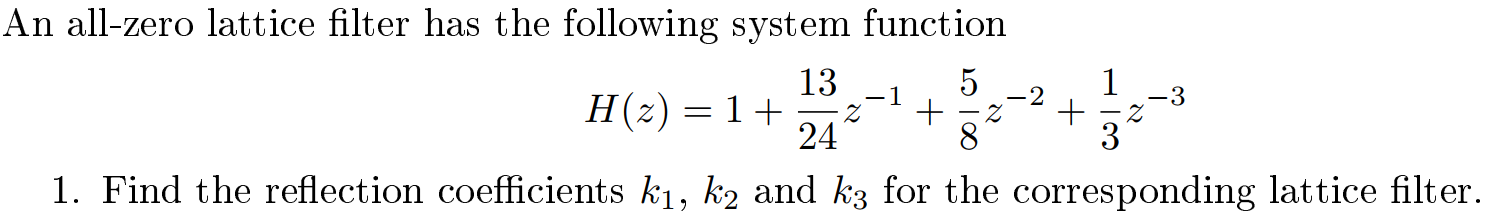

We use the MATLAB function ***tf2latc*** to convert transfer function filter parameters to lattice filter form

b = [1, 13/24, 5/8, 1/3];
a = 1;
k = tf2latc(b, a)

k =     0.2500
    0.5000
    0.3333


We can also try the algorithm (Figure 9.24) from the book

k = fir2lat(b)

k =     0.2500    0.5000    0.3333


Both functions agree! 

The reflection coefficients are $k_1 =\frac{1}{4},k_2 =\frac{1}{2},k_3 =\frac{1}{3}$

## ADSI Problem 2.5: All-zero lattice filter, find coefficients from system function

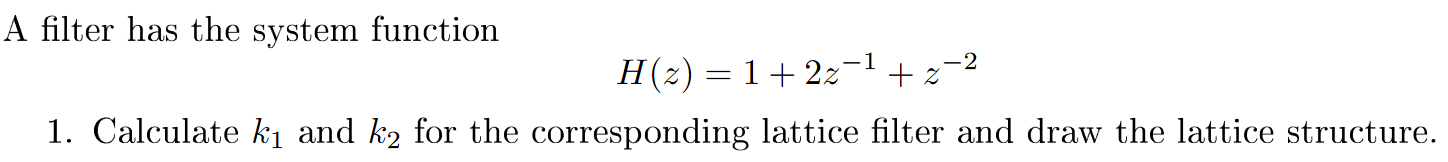

We cannot use a recursive algorithm because one of the reflection coefficients is equal to 1

b = [1, 2, 1];
a = 1;
% tf2latc(b) % This fails because one coeff. is 1

Instead we can use a cascade of two single stage filters.

First, we find the two roots:

roots(b)

ans =     -1
    -1


Next, we factorise the original FIR filter to two cascade filters:


$$H\left(z\right)=\left(1-\left(-1\right)z^{-1} \right)\left(1-\left(-1\right)z^{-1} \right)=\left(1+z^{-1} \right)\left(1+z^{-1} \right)$$


We know that a single stage all-zero filter has following difference equation:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 x\left\lbrack n-1\right\rbrack$$


Taking the z-transform we get:


$$Y_{\mathrm{az}} \left(z\right)=X_{\mathrm{az}} \left(z\right)+k_1 X_{\mathrm{az}} \left(z\right)z^{-1}$$


The system function of a single stage all-zero lattice filter is therefore:


$$H_{\mathrm{az}} \left(z\right)=\frac{Y_{\mathrm{az}} \left(z\right)}{X_{\mathrm{az}} \left(z\right)}=1+k_1 z^{-1}$$


It turns out that we can cascade two single stage all-zero lattice filters.

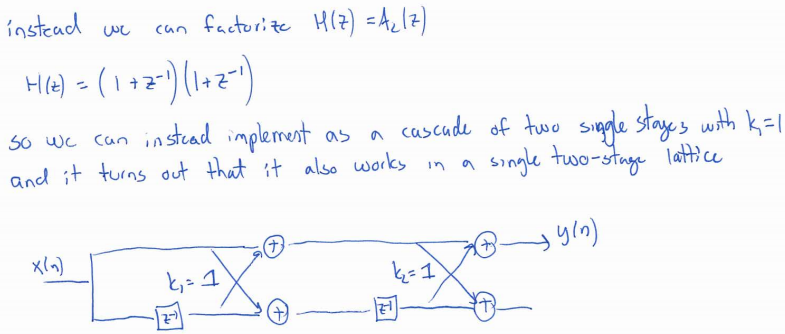

So in our case, we have $k_1 =1$ and $k_2 =1$.

Let us check if we can get the impulse response of the original filter.

k = [1, 1];
lat2fir(k, 1)

ans =      1     2     1


latc2tf(k) % Same as lat2fir

ans =      1     2     1


Success! 

## ADSI Problem 2.7: Find system function an all-pole filter from reflection coefficients

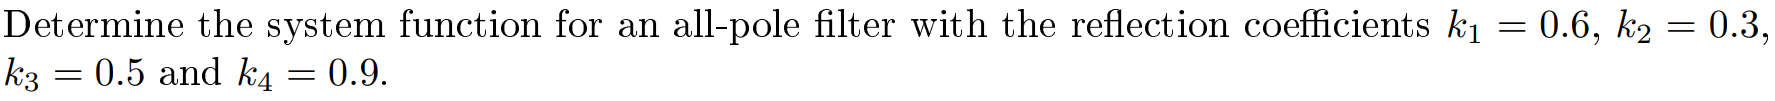

We can use MATLAB function latc2tf

k = [0.6, 0.3, 0.5, 0.9];
[num, dem] = latc2tf(k, 'allpole')

num =      1     0     0     0     0


dem =     1.0000    1.3800    1.3110    1.3370    0.9000


The system function is:


$$H\left(z\right)=\frac{1}{1+1\ldotp 38z^{-1} +1\ldotp 311z^{-2} +1\ldotp 337z^{-3} +0\ldotp 9z^{-4} }$$


## ADSI Problem 2.10: Linear prediction and lattice filters  

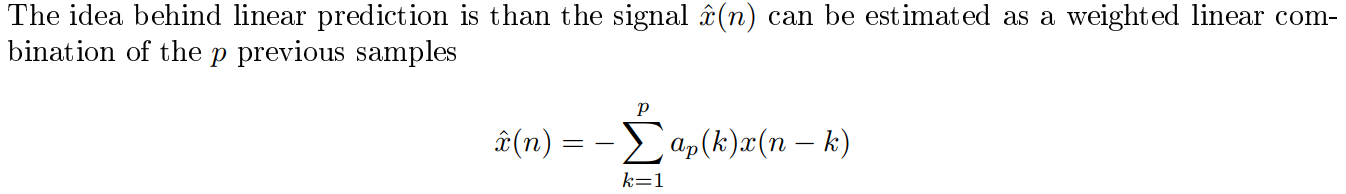

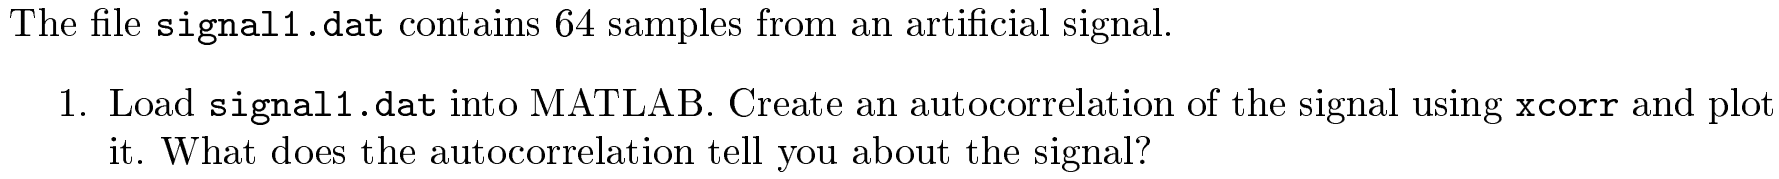

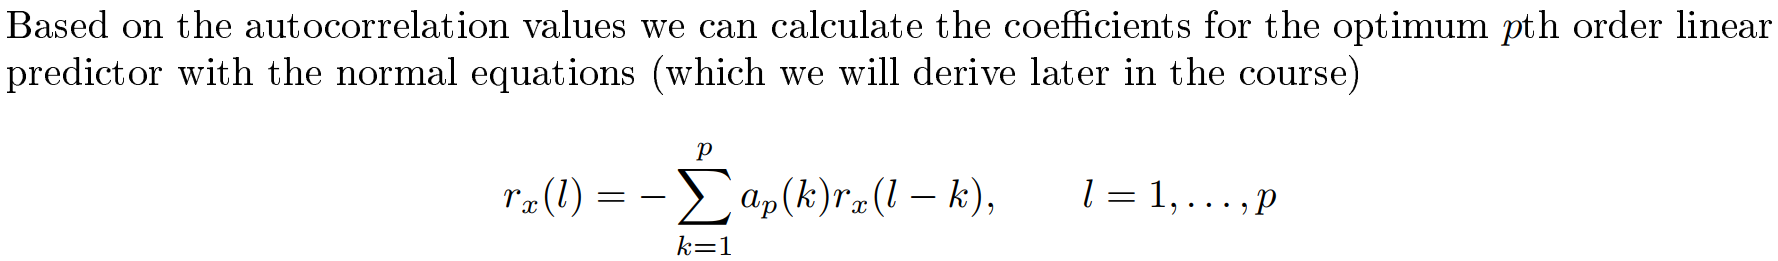

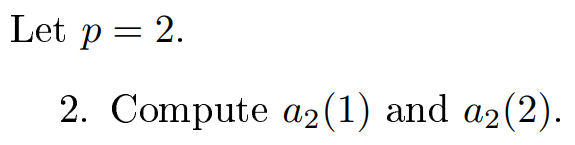

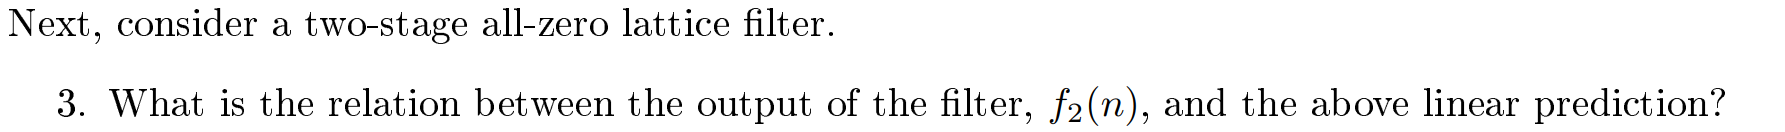

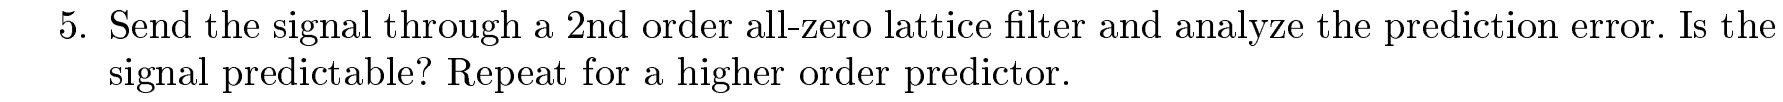

## ADSI Problem 2.11 (Optional): The digital state variable filter

One interesting filter structure is the digital state variable filter which has its roots in the analog state variable filter. It can be considered as a standard second order filter, but with the valuable feature that the center frequency and Q-factor are independently tuneable. The structure of the filter is shown here  

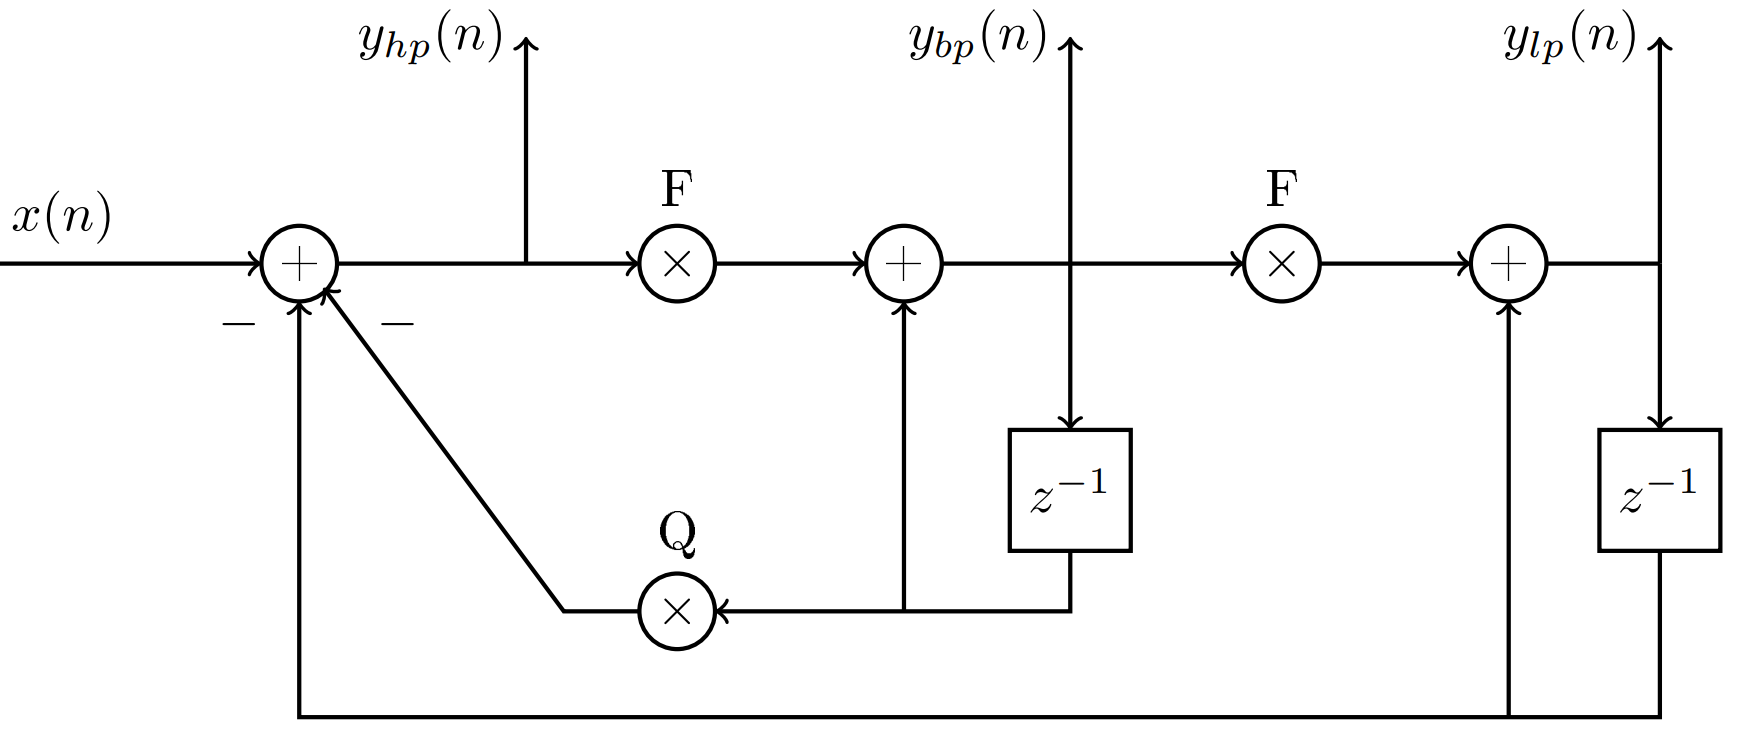

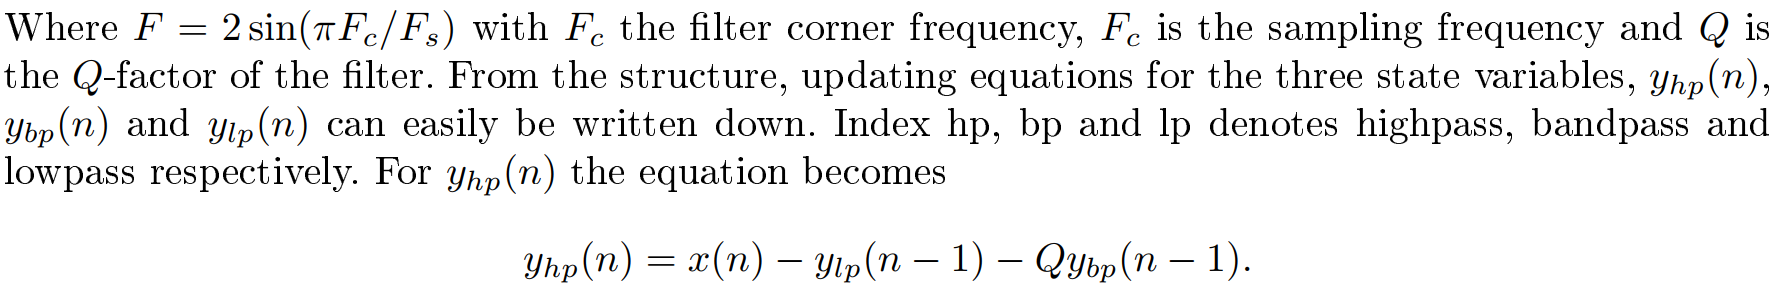

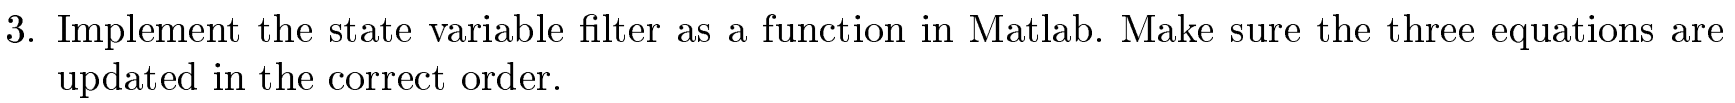

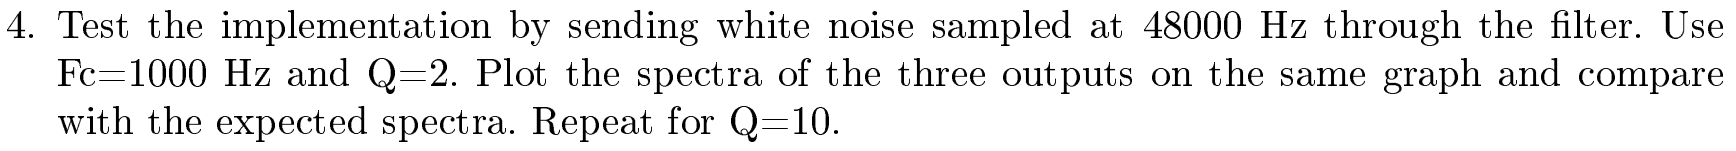

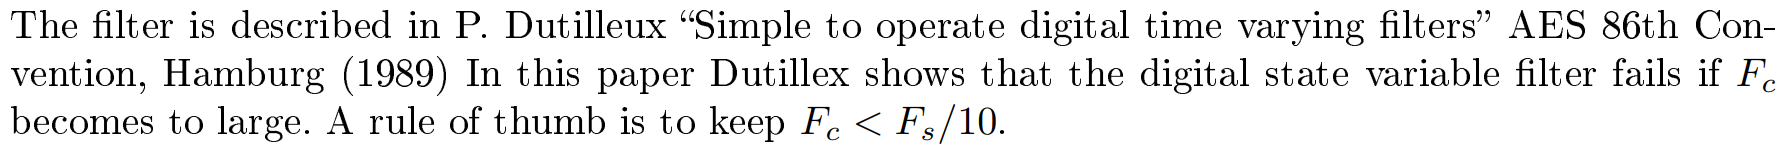

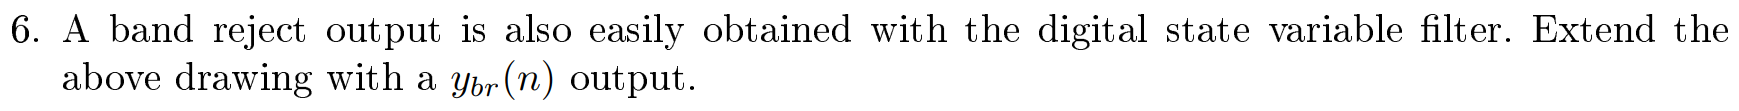

## Functions

function [y] = azlatfilt(k, x, G)
% AZLATFILT      Function for implementation of an all-zero FIR lattice filter
% From Figure 9.26 (p 515)

    M = length(k); 
    
    % Create an array for the sequence f_m[n]
    f = zeros(1,M); 
    
    % Create an array for the sequence g_m[n]
    g = f;
    
    % Create an array for the sequence g_m[n-1]
    oldg = zeros(1,M);
    
    % Keeps track of x[n-1]
    oldx = 0;
    x = G*x; 
    y = zeros(size(x));
    
    for n=1:length(x)
        % Compute f1[n] = x[n] + k1x[n ? 1] -> Equation (9.57a)
        f(1) = x(n)+k(1)*oldx;
        
        % Compute g1[n] = k1x[n] + x[n ? 1] -> Equation (9.57b)
        g(1) = k(1)*x(n)+oldx;
        oldx = x(n);
        for m = 2:M
            % Compute: fm[n] = fm?1[n] + km gm?1[n ? 1] -> Equation (9.55a)
            f(m) = f(m-1)+k(m)*oldg(m-1);
            
            % Compute: gm[n] = km fm?1[n] + gm?1[n ? 1] -> Equation (9.55b)
            g(m) = k(m)*f(m-1)+oldg(m-1);
            
            % Delay
            oldg(m-1) = g(m-1);
        end
        
        % y[n] = fM[n] -> Equation (9.56b)
        y(n) = f(M);
    end
end


function [k,G] = fir2lat(h)
% Converts FIR filter coefficients to lattice coefficients.
% From Figure 9.24 (p. 514)
    G = h(1); 
    a = h/G;
    M = length(h)-1; 
    k(M) = a(M+1);
    for m = M:-1:2
        b = fliplr(a);
        a = (a-k(m)*b)/(1-k(m)^2); a = a(1:m);
        k(m-1) = a(m);
    end
end

function h = lat2fir(k, G)
% Converts lattice coefficients to FIR filter coefficients.
% From Figure 9.25 (p. 515)
    a = 1; 
    b = 1; 
    M = length(k);
    for m = 1:1:M
        a = [a,0]+k(m)*[0,b];
        b = fliplr(a);
    end
    h = G*a;
end
